# Invariant Transformation of Alvarez and Lopez

## What is it?

The Alvarez and Lopez invariant transform is a method for obtaining an image that is robust to illumination variations, such as shadows and changes in light intensity. This is achieved by converting the pixel values to logarithmic-chromatic space and projecting them in a specific direction.

## Basic operation of the transformation

**1. Conversion to logarithmic-chromatic space:**

Each pixel of the image $RGB$ is converted to logarithmic-chromatic space using the following formula:


$$r = \log \frac{R}{G}, \quad b = \log \frac{B}{G}$$


where:

- $R$, $G$, y $B$ are the values of the red, green and blue color channels, respectively.

**2. Projection in the Invariant direction:**

The invariant angle $\theta$ is determined by minimizing the entropy of the projected image. The value of $\theta$ is obtained by solving the following optimization problem:


$$E_{\alpha} = -\sum_{i=1}^{L} H_{\alpha}(i) \log H_{\alpha}(i)$$


where:

- $H_{\alpha}$ is the projection histogram in a direction of slope $\alpha$.

Once the invariant angle is obtained, the chromatic values are projected in the $\theta$ direction to obtain the invariant image:


$$I = r \cos\theta + b \sin\theta$$


## Implementation analysis:

**1. Input parameters:**

- $RGB$: image in RGB format.

- $theta$: angle invariant to illumination.

- $alpha$: parameter for logarithmic approximation.

**2. Calculation of the ratio between the channels:**

First, the function converts the image to the double type and calculates the relationships between the color channels.

R = double(RGB(:,:,1));
G = double(RGB(:,:,2));
B = double(RGB(:,:,3));

RB_ratio = R ./ B; % Relación rojo-azul
GB_ratio = G ./ B; % Relación verde-azul

**3. Logarithmic approximation:**

A logarithmic approximation is then used to calculate the ratios between the red-to-blue and green-to-blue channels.

log_approx_RB = alpha * ((RB_ratio / alpha) - 1);
log_approx_GB = alpha * ((GB_ratio / alpha) - 1);

This is a simplification of the logarithmic formula:


$$r = \log \frac{R}{G}, \quad b = \log \frac{B}{G}$$


**4. Invariant transformation:**

Finally, the function performs the invariant transformation by projecting onto the angle $\theta$:

I_Alvarez = cos(theta) * log_approx_RB + sin(theta) * log_approx_GB;

This is consistent with the formula:


$$I = r \cos\theta + b \sin\theta
$$


where:

- $r$ represents the logarithmic ratio red - green.

- $b$ represents the logarithmic ratio blue - green.

### Complete code

function I_Alvarez = alvarez_transform(RGB, theta, alpha)
    % RGB image separation by channels in double
    R = double(RGB(:,:,1));
    G = double(RGB(:,:,2));
    B = double(RGB(:,:,3));
    
    % Calculate the relationships between red-blue and green-blue channels.
    RB_ratio = R ./ B;
    GB_ratio = G ./ B;
    
    % Logarithmic approximation RB and GB
    log_approx_RB = alpha * ((RB_ratio / alpha) - 1);
    log_approx_GB = alpha * ((GB_ratio / alpha) - 1);
    
    % Invariant transformation
    I_Alvarez = cos(theta) * log_approx_RB + sin(theta) * log_approx_GB;
end

An example of a program image and its corresponding transformation:

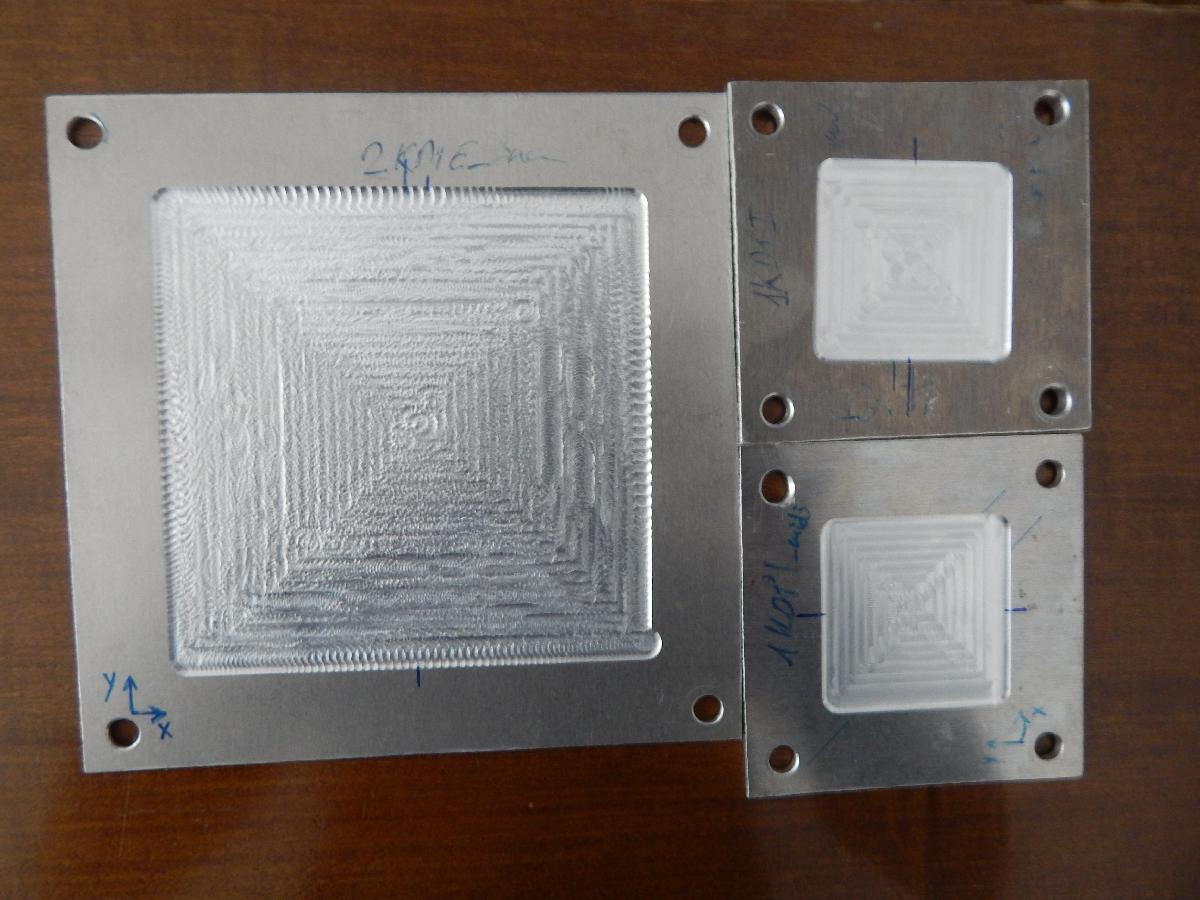    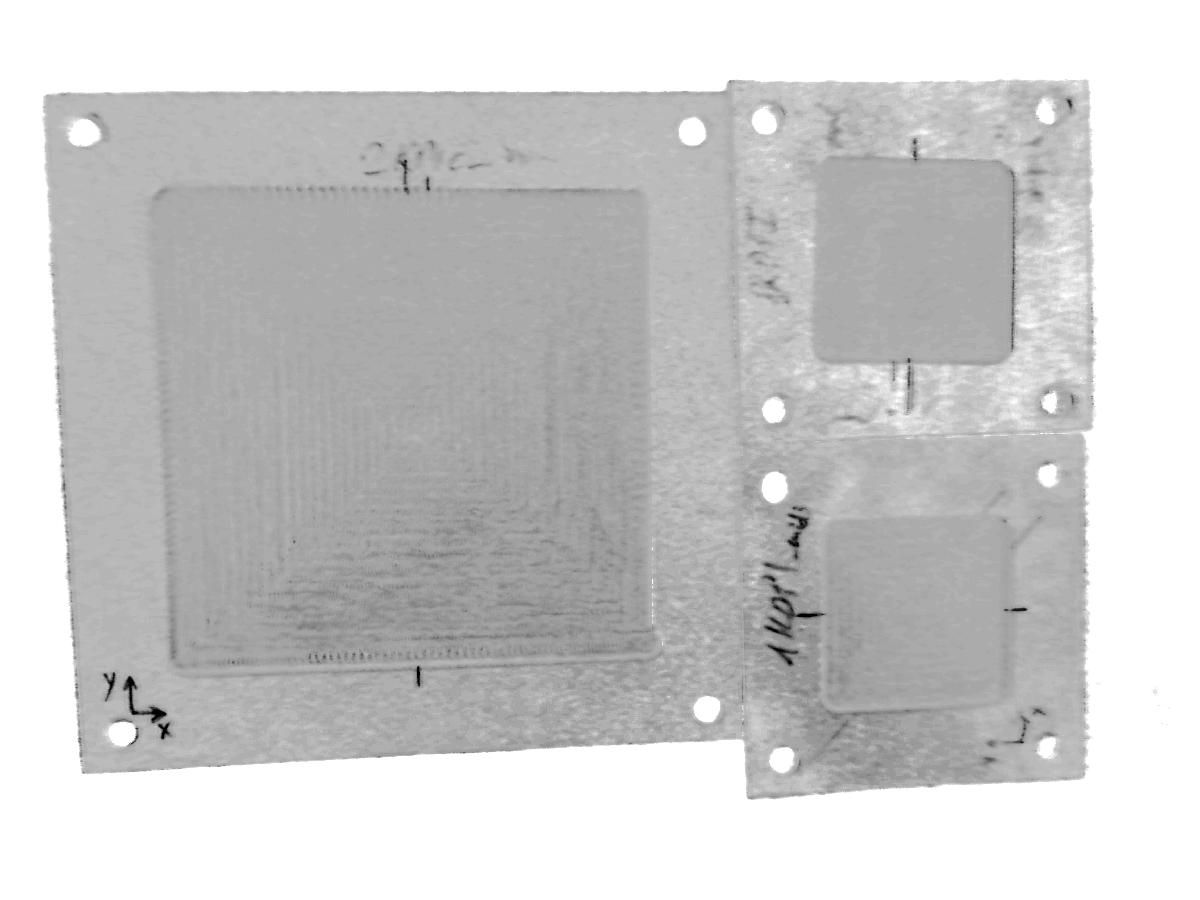

## References

- Álvarez, J. M., & López, A. M. "Road detection based on illuminant invariance," *IEEE Transactions on Intelligent Transportation Systems*, vol. 12, no. 1, pp. 184-193, Mar. 2011.